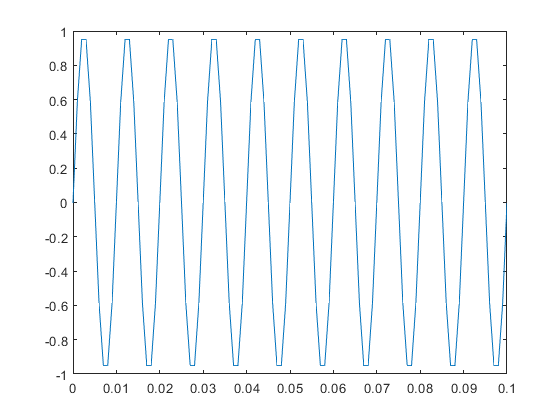

f=100;
fs=1000;
dt=1/fs;
tf=0.1;
t=0:dt:tf;
signal=sin(2*pi*f*t);
plot(t,signal)

signal_n=awgn(signal,15)

signal_n =    -0.1540    0.6199    1.1763    0.9064    0.5514   -0.3915   -0.7255   -1.1988   -1.0197   -0.4943    0.2709    0.9076    0.9303    0.8941    0.7332    0.0872   -0.4517   -0.8127   -1.2143   -0.4917   -0.0163    0.4526    0.8277    1.1789    0.4438   -0.2199   -0.5496   -0.5935   -0.9465   -0.5330   -0.1668    0.8855    0.9733    1.0453    0.4185    0.1519   -0.5186   -1.1566   -0.9440   -0.6679    0.0194    0.5432    0.9173    0.7674    0.5303    0.1363   -0.2775   -1.1574   -0.5283   -0.3164


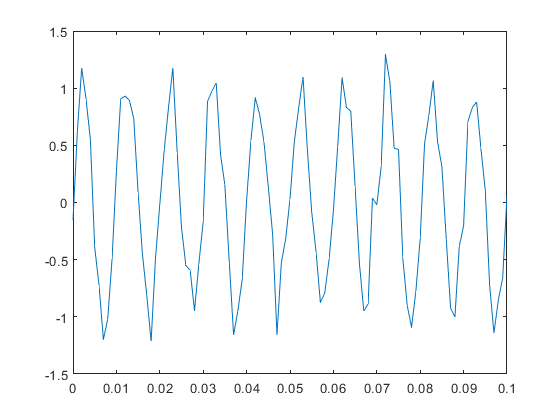

plot(t,signal_n)

Filter function at the end of the code

lambda=0.7

lambda = 0.7000

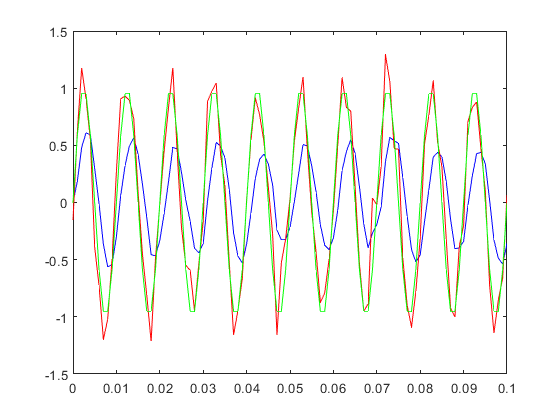

sig_f=LI_7(0,signal_n,lambda);
plot(t,sig_f,'b',t,signal_n,'r',t,signal,'g')

b=[1-lambda]

b = 0.3000

a=[1,-lambda]

a =     1.0000   -0.7000


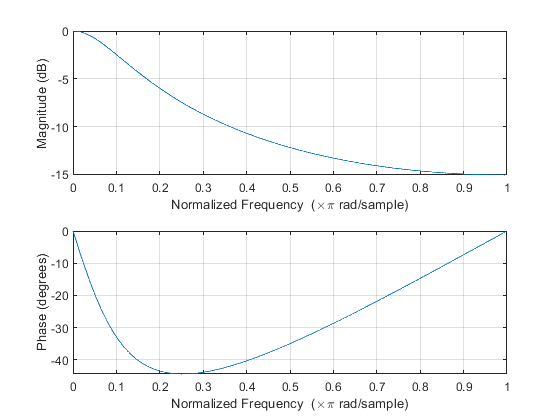

freqz(b,a)

fco=-log(lambda)*fs/pi

fco = 113.5332

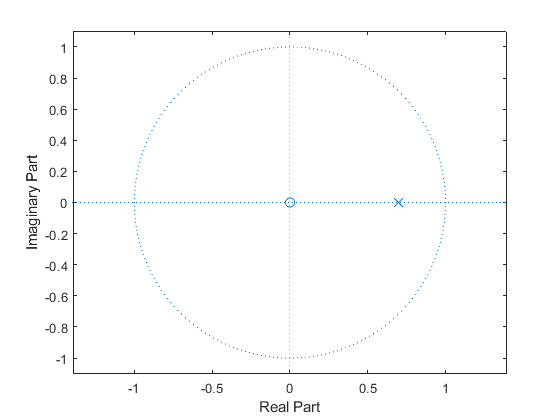

zplane(b,a)

El filtro es estable

filter()

Functions defined

function y=LI_7(y0,sig_2filter,lambda)
    y(1)=y0;
    for i=2:length(sig_2filter)
        y(i)=y(i-1)*lambda+(1-lambda)*sig_2filter(i);
    end
end